clc;
close all;
clear all;
pd = makedist('Nakagami','mu',9,'omega',6);
msg= random(pd,1000,1);
data=[];
t=0:.01:.99;
c=cos(2*pi*10*t);%carrier signal & it's a matrix of length 1X100(bcoz for each t, there's a c).let fc=10hz
for i=1:10
    if msg(i)<=0
        d=-1*ones(1,10);
    else
        d=ones(1,10);
    end
 data=[data d];   
end
 Bfsk=[];
for i=1:100
 Bfsk=[Bfsk cos(2*pi*10*t+(msg(i)*2*pi*5*t))];
end

x = 1; % signal to transmit Eb = 1
T = 10000; %number of simulation runs per EbN0 %50000
N=10^6;
for EbN0 = 0:1:35 %dB
    NdB_EbN0= 10^(EbN0/10); 
    E_b = 1/(NdB_EbN0); 
    error1 = 0;
    err=0; %set error counter to 0
    error2=0;
    for t = 1:T %  count the erro
            gaussian_1 = sqrt(E_b/2)*randn; %noise for the first
            gaussian_2 = sqrt(E_b/2)*randn; %noise for the 2nd
            rayleigh_1 = sqrt(0.5)*abs(randn + 1i*randn); %rayleigh noise
            rayleigh_2 = sqrt(0.5)*abs(randn + 1i*randn);
            Added_noise_1=sqrt(E_b/2)*randn+sqrt(0.5)*abs(randn + 1i*randn);
            Added_noise_2=sqrt(E_b/2)*randn+sqrt(0.5)*abs(randn + 1i*randn);
            %Equal Gain combining
            EGC1 = x*Bfsk+rayleigh_1; 
            EGC2 = x*Bfsk+gaussian_2;
            EGC =  0.5*(EGC1+EGC2); 
            if EGC > 0 %define decision region as 0 
               error1 = error1 + 1;
            end
            % selection combinig 
            amp_1 = (abs(Bfsk)).^2; % Ri^2+Ni
            amp_2 = (abs(Bfsk)).^2;
            if amp_1 >= amp_2
                SC_Branch = x.*(amp_1*gaussian_1)+amp_1.*Added_noise_1;
            end
            if amp_1 < amp_2
                SC_Branch = x.*(amp_2*gaussian_2 )+amp_2.*Added_noise_2;
            end
            if SC_Branch < 0 
                err = err+ 1;
            end
            %MRC
            %Maximal Ratio combining
            amp = (abs(Bfsk)).^2;
            maximal_ratio_comb = x*(amp*rayleigh_1)+amp*gaussian_1;
             if maximal_ratio_comb < 0 
                error2 = error2 + 1;
             end
        end

    BER2(EbN0+1) = error2/(T);
    BER1(EbN0+1) = err/(T);
    BER(EbN0+1) = error1/(T);
end

gam0 = 5;
av_snr2=[];
av_snr1=[];
snr=[1:35];
fun_1 = makedist('Nakagami','mu',5,'omega',3);
    nakagami_1 = random(fun_1,1000,1);
    fun_2 = makedist('Nakagami','mu',5,'omega',2);
    nakagami_2 = random(fun_2,1000,1);
%nakagami_1=sqrt(0.5)*abs(randn(1000,1)+1i*randn(1000,1)); %rayleigh channel 1
%nakagami_2=sqrt(0.5)*abs(randn(1000,1)+1i*randn(1000,1)); %rayleigh channel 2
%%Adding Noise
A=[];
B=[];
for i=1:length(snr)
    sig1=awgn(nakagami_1,snr(i));
    A=[A,sig1];
    sig2=awgn(nakagami_2,snr(i));
    B=[B,sig2];
end
n=size(A);
for k=1:n(2)
    asn1=A(:,k);
    asn2=B(:,k);
    avg=0;
    aa=0;
for i=1:length(B)
    wgt=(abs(asn1(i))^2)+(abs(asn2(i))^2)/2;
    avg=avg+wgt;
    aa=aa+abs(asn1(i)^2);
end
av_snr2=[av_snr2,avg];
av_snr1=[av_snr1,aa];
end
gr = gam0./(snr.*av_snr2);
gr1 = gam0./(snr.*av_snr1);
for i = 1:length(gr)
    pout2(i) = (1-(exp(-2*gr(i)))-((sqrt(pi*gr(i)))*(exp(-gr(i)))))*(1-2*(erfc(sqrt(gr(i)))));
    pout1(i) = (1-(exp(-2*gr1(i)))-((sqrt(pi*gr1(i)))*(exp(-gr1(i)))))*(1-2*(erfc(sqrt(gr1(i)))));
end
%plotting of figure

subplot(411);
plot(msg);
title('nakagami m data');

subplot(412);
plot(data);axis([0 100 -1.5 1.5])
title('Digital data');
subplot(413)
plot(c);axis([0 100 -1.5 1.5])
title('Unmodulated carrier');
 
%disp(data);
disp(Bfsk);

  Column 1

    1.0000

  Column 2

    0.2672

  Column 3

   -0.8572

  Column 4

   -0.7253

  Column 5

    0.4696

  Column 6

    0.9763

  Column 7

    0.0522

  Column 8

   -0.9484

  Column 9

   -0.5590

  Column 10

    0.6496

  Column 11

    0.9062

  Column 12

   -0.1653

  Column 13

   -0.9946

  Column 14

   -0.3662

  Column 15

    0.7988

  Column 16

    0.7931

  Column 17

   -0.3749

  Column 18

   -0.9935

  Column 19

   -0.1560

  Column 20

    0.9101

  Column 21

    0.6424

  Column 22

   -0.5668

  Column 23

   -0.9454

  Column 24

    0.0616

  Column 25

    0.9783

  Column 26

    0.4612

  Column 27

   -0.7318

  Column 28

   -0.8523

  Column 29

    0.2763

  Column 30

    1.0000

  Column 31

    0.2582

  Column 32

   -0.8620

  Column 33

   -0.7188

  Column 34

    0.4778

  Column 35

    0.9742

  Column 36

    0.0428

  Column 37

   -0.9513

  Column 38

   -0.5512

  Column 39

    0.6567

  Column 40

    0.9022

  Column 

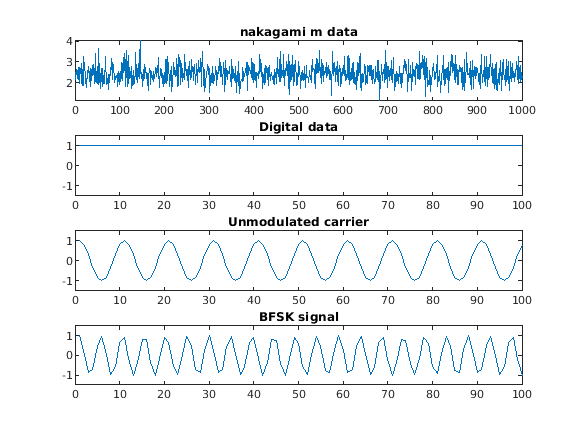

subplot(414);
plot(Bfsk);axis([0 100 -1.5 1.5])
title('BFSK signal');

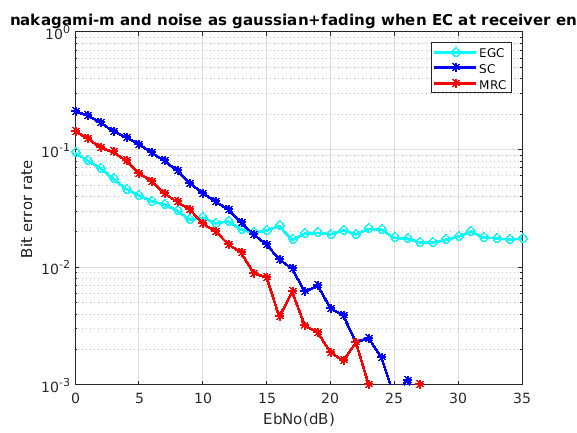

figure
EbNo=0:1:35; %changed from 10
linear_EbNo = 10.^(EbNo/10);
theoryBerAWGN = 0.5*erfc(sqrt(10.^(EbNo/10)));
theoryBer = 0.5.*(1-sqrt(linear_EbNo ./(linear_EbNo +1)));
semilogy(EbNo,BER,'c-o',EbNo,BER1,'b*-',EbNo,BER2,'r*-','linewidth',2);% plot EG BER vs EbNo
hold on;
grid on;
axis([0 35 10^-3 1])
legend('EGC','SC','MRC');
xlabel('EbNo(dB)') %Label for x-axis
ylabel('Bit error rate') %Label for y-axis
title('nakagami-m and noise as gaussian+fading when EC at receiver end');

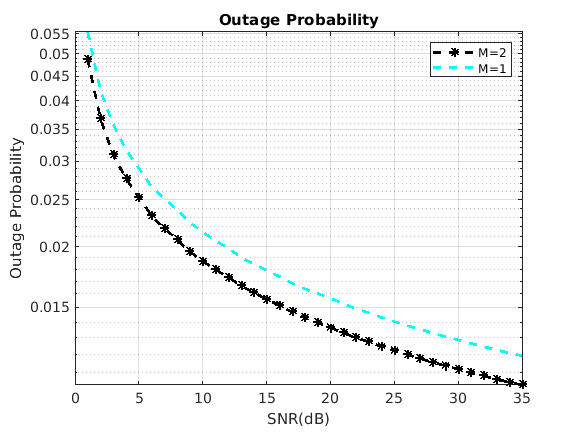


figure()
semilogy(snr,pout2,'k*--',snr,pout1,'c--','linewidth',2);

hold on;

grid on;
 xlabel('SNR(dB)');
 ylabel('Outage Probability');
 legend('M=2','M=1')
title('Outage Probability')